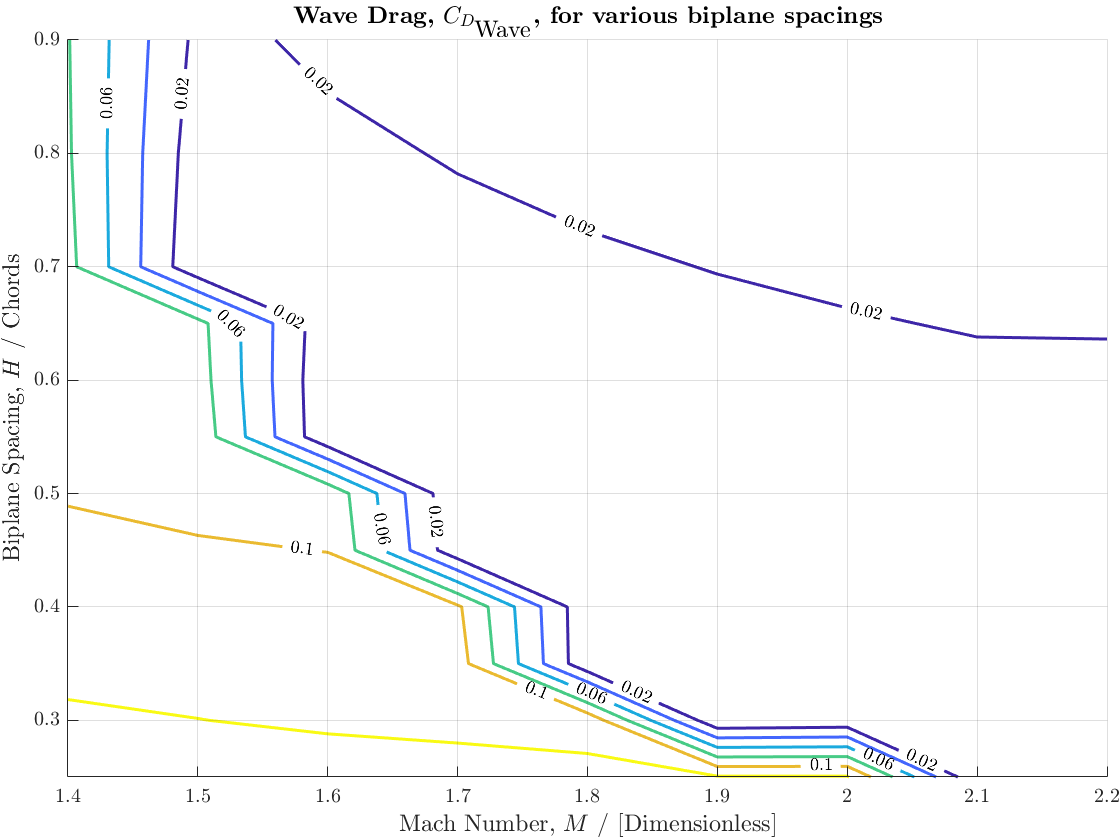

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 12 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
Machs = [1.4:0.1:2.2];
Spacings = [0.25,0.3,0.35,0.4,0.45,0.5,0.55,0.6,0.65,0.7,0.8,0.9];
[X,Y] = meshgrid(Machs,Spacings);
%CdWave = X.*exp(-X.^2-Y.^2);
CdWave =[0.13372300	0.13028900	0.12843600	0.12571900	0.12430100	0.12184200	0.12174800	0.00233426	0.00358751;
0.12279100	0.12024500	0.11735400	0.11616500	0.11391800	0.00329463	0.00587150	0.00512922	0.00373783;
0.11516700	0.11282700	0.10999800	0.10870100	0.00471196	0.00547467	0.00350509	0.00219628	0.00170952;
0.10908500	0.10637700	0.10486200	0.10309300	0.00469977	0.00252141	0.00201319	0.00296174	0.00408375;
0.10352000	0.10115000	0.09981180	0.00535090	0.00217566	0.00292894	0.00447685	0.00606766	0.00756879;
0.09898930	0.09674000	0.09506661	0.00245183	0.00380087	0.00588249	0.00792598	0.00974116	0.01128010;
0.09428540	0.09220460	0.00427997	0.00408049	0.00680191	0.00942348	0.01162840	0.01346520	0.01501310;
0.09064270	0.08857450	0.00371171	0.00699493	0.01033840	0.01309540	0.01533910	0.01716340	0.01875940;
0.08805110	0.08629830	0.00615269	0.01039850	0.01399980	0.01678430	0.01900980	0.02089040	0.02047060;
0.08540880	0.00431752	0.00917551	0.01404110	0.01767750	0.02047610	0.02264410	0.02170960	0.02045660;
0.08196310	0.00900950	0.01614780	0.02131250	0.02501000	0.02483000	0.02313210	0.02170760	0.02046580;
0.08087570	0.01502350	0.02336090	0.02856780	0.02684870	0.02486010	0.02318650	0.02173330	0.02048350];
 
figure
[C,h] = contour(X,Y,CdWave,'ShowText','on',"LineWidth",width);
v = [0.02 0.06 0.1 0.2];
clabel(C,h,v,'FontSize',legsize,'LabelSpacing',150,'Interpreter','latex')
grid on; box off; hold on
title("\textbf{Wave Drag,} $C_{D_\textrm{Wave}}$\textbf{, for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off

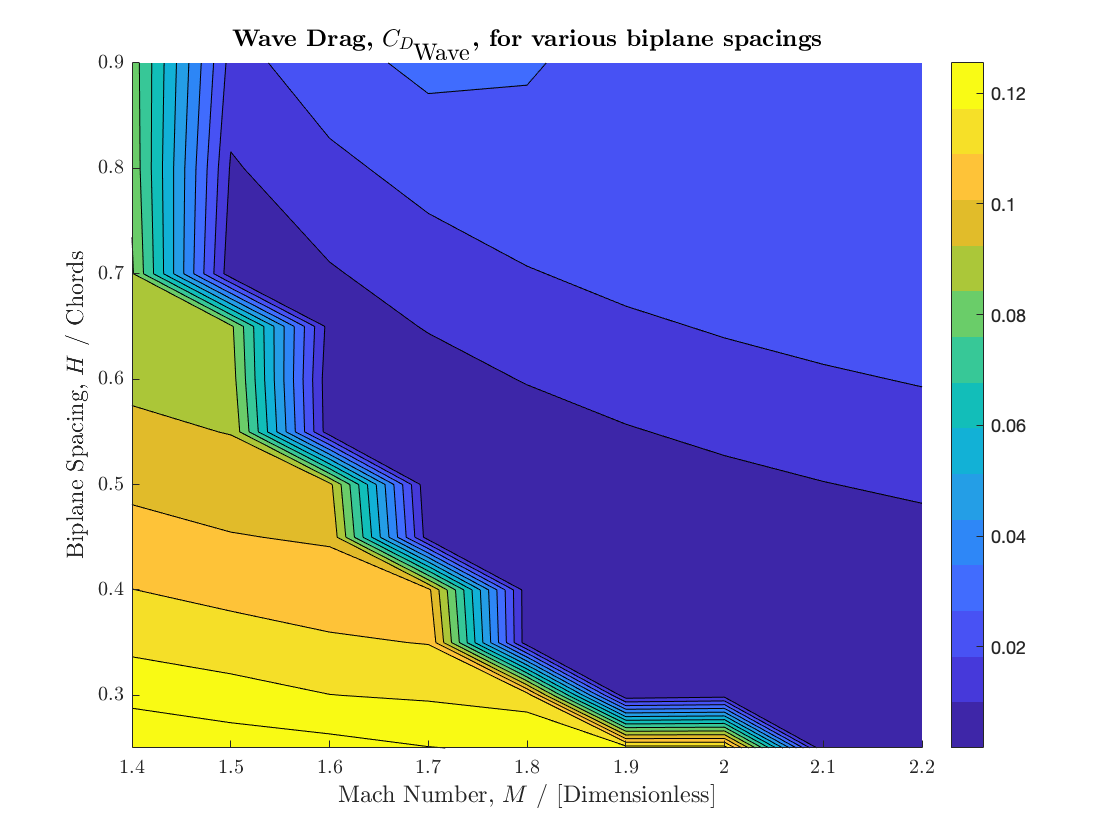

 
figure
numcolours = 15;
%contour(X,Y,CdWave,20,"LineWidth",width)
contourf(X,Y,CdWave,numcolours)%,"LineStyle","none")
box off; hold on; %grid on
title("\textbf{Wave Drag,} $C_{D_\textrm{Wave}}$\textbf{, for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
colormap(parula(numcolours));
colorbar;
%InSet = get(gca, 'TightInset');
%set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off

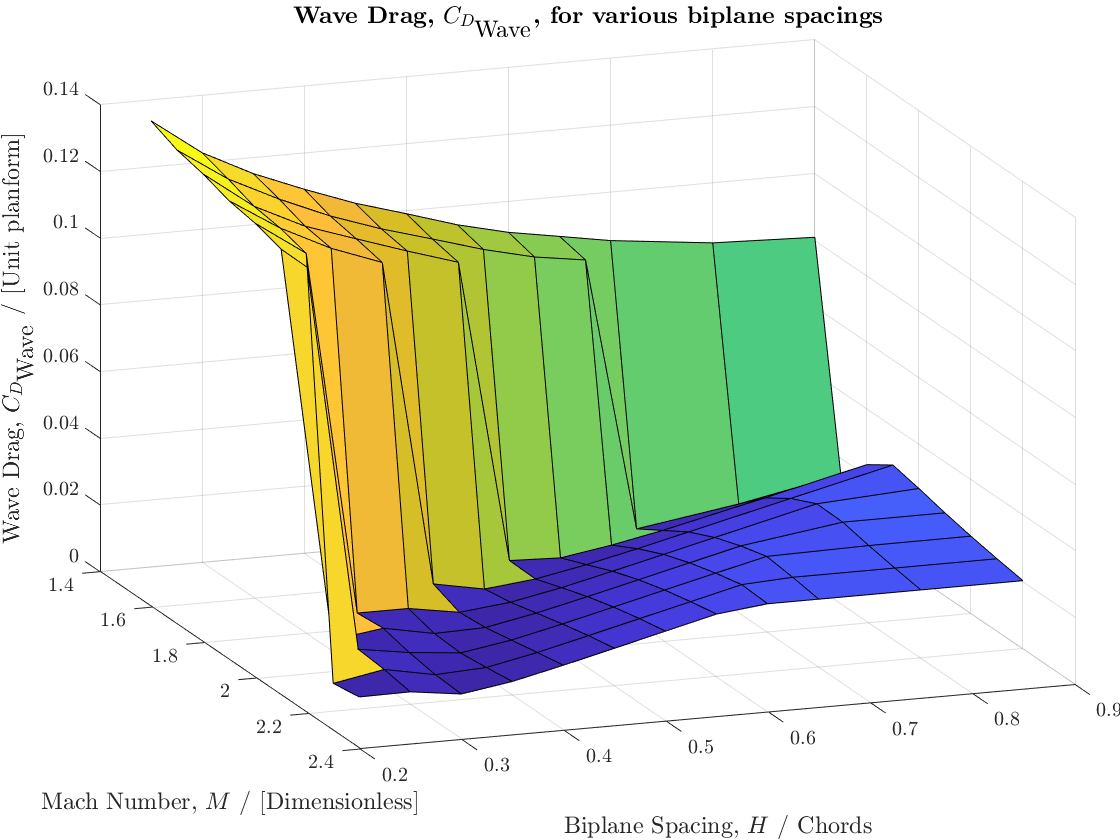

 
figure
surf(X,Y,CdWave)
grid on; box off; hold on
title("\textbf{Wave Drag,} $C_{D_\textrm{Wave}}$\textbf{, for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
ylim([0.2 0.9])
view([70 22])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off

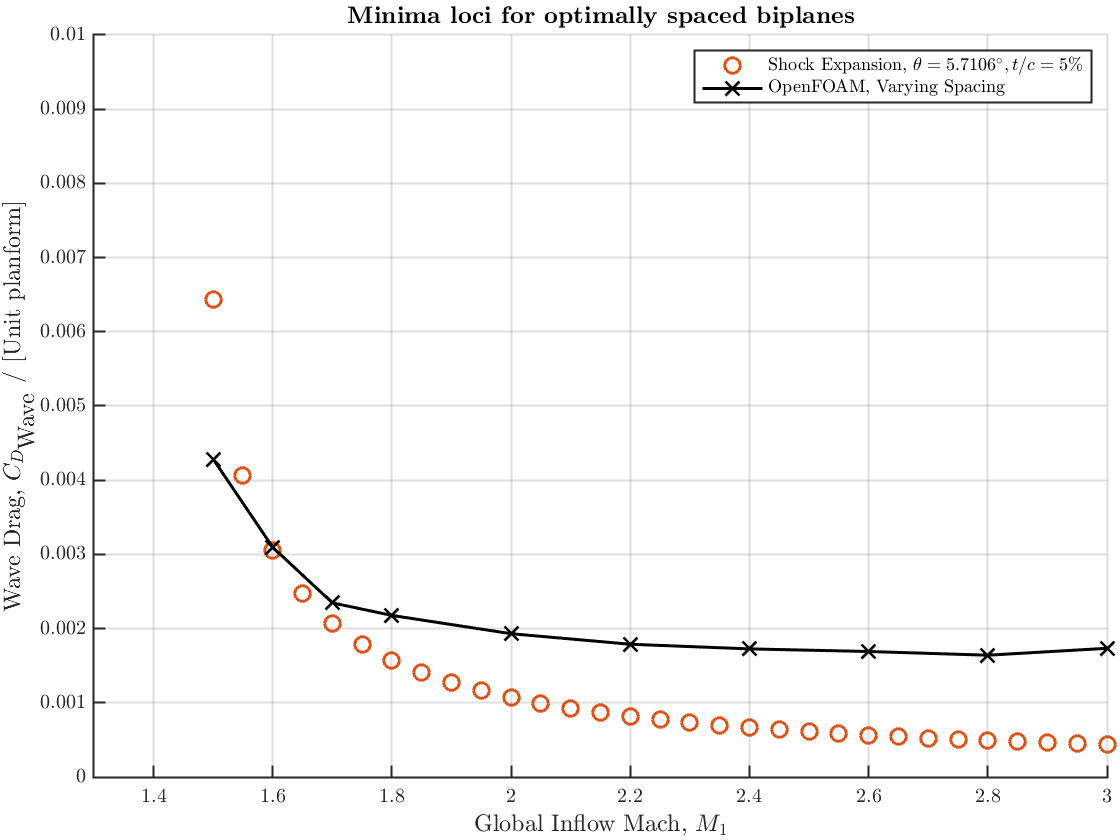



SE_mach = [1.5:0.05:3];
SE_cdwave = [0.00642902085987744,0.00405914684323645,0.00305779621962136,0.00246781778488710,...
	0.00207278541090180,0.00178843868217877,0.00157373283220522,0.00140591110402178,0.00127122298160687,...
	0.00116082848712197,0.00106877023633856,0.000990881185487782,0.000924157104392445,0.000866377044477652,...
	0.000815863951573243,0.000771328284379501,0.000731762766506605,0.000696369709528625,0.000664509690839535,...
	0.000635664590105752,0.000609410497387429,0.000585397543800950,0.000563334673534854,0.000542977999915937,...
	0.000524121799036560,0.000506591470206303,0.000490237980897177,0.000474933444604994,0.000460567572166534,...
	0.000447044802878520,0.000434281969271938];

foam_mach = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
foam_cdwave = [0.00428408,0.00309546,0.00234688,0.00217738,0.00193102,0.00178917,0.00172647,...
0.00169135,0.00164138,0.00173464];

foam_spacing=[0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];
foam_cellcount = [23512,21122,20026,19618,18368,18192,17780,17606,17166,16744];

figure
%plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",width,"MarkerSize",8)
%plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
hold on
plot(SE_mach,SE_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(foam_mach,foam_cdwave,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('Shock Expansion, $\theta= 5.7106^{\circ}, t/c=5\%$','OpenFOAM, Varying Spacing','location','northeast','FontSize',legsize)
xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Minima loci for optimally spaced biplanes}",'FontSize',tsize)
ylim([0,0.01])
xlim([1.3, 3])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

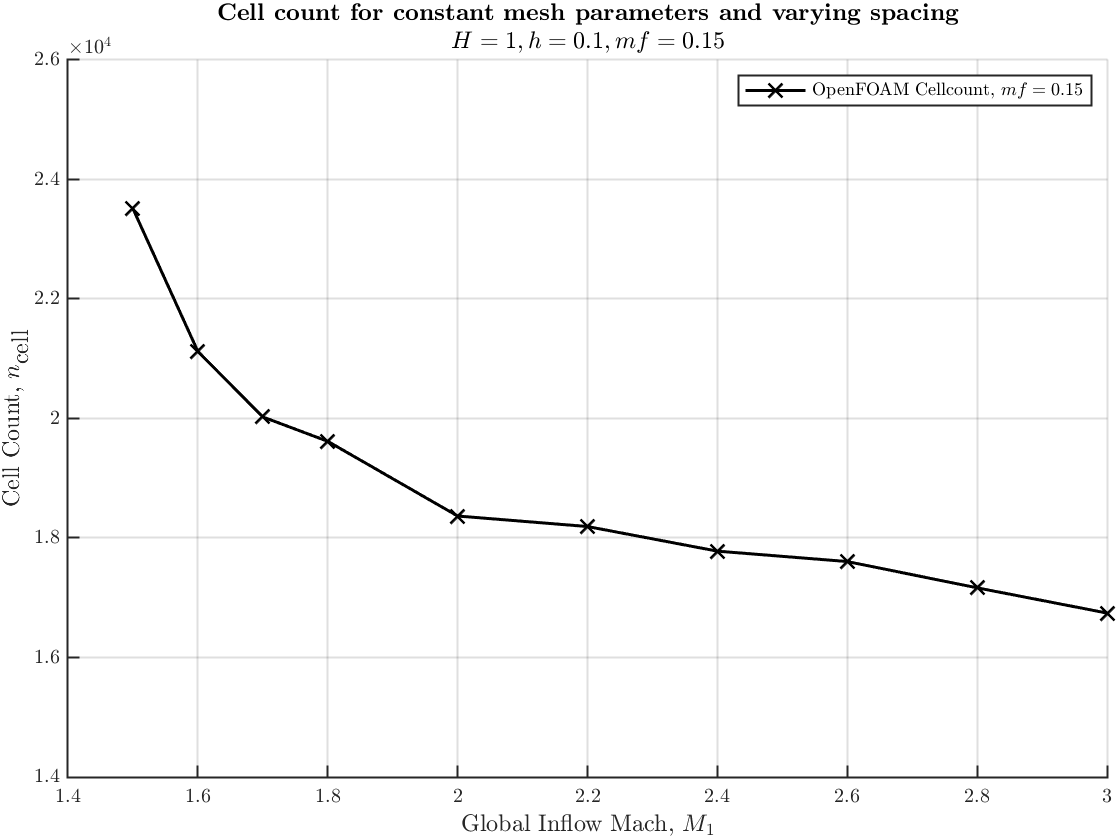


figure
hold on
plot(foam_mach,foam_cellcount,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('OpenFOAM Cellcount, $mf = 0.15$','location','northeast','FontSize',legsize)
xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
ylabel("Cell Count, $n_{\textrm{cell}}$",'FontSize',lsize)
title([{"\textbf{Cell count for constant mesh parameters and varying spacing}","$H=1,h=0.1,mf=0.15$"}],'FontSize',tsize)
ylim([1.4e4,2.6e4])
xlim([1.4, 3])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

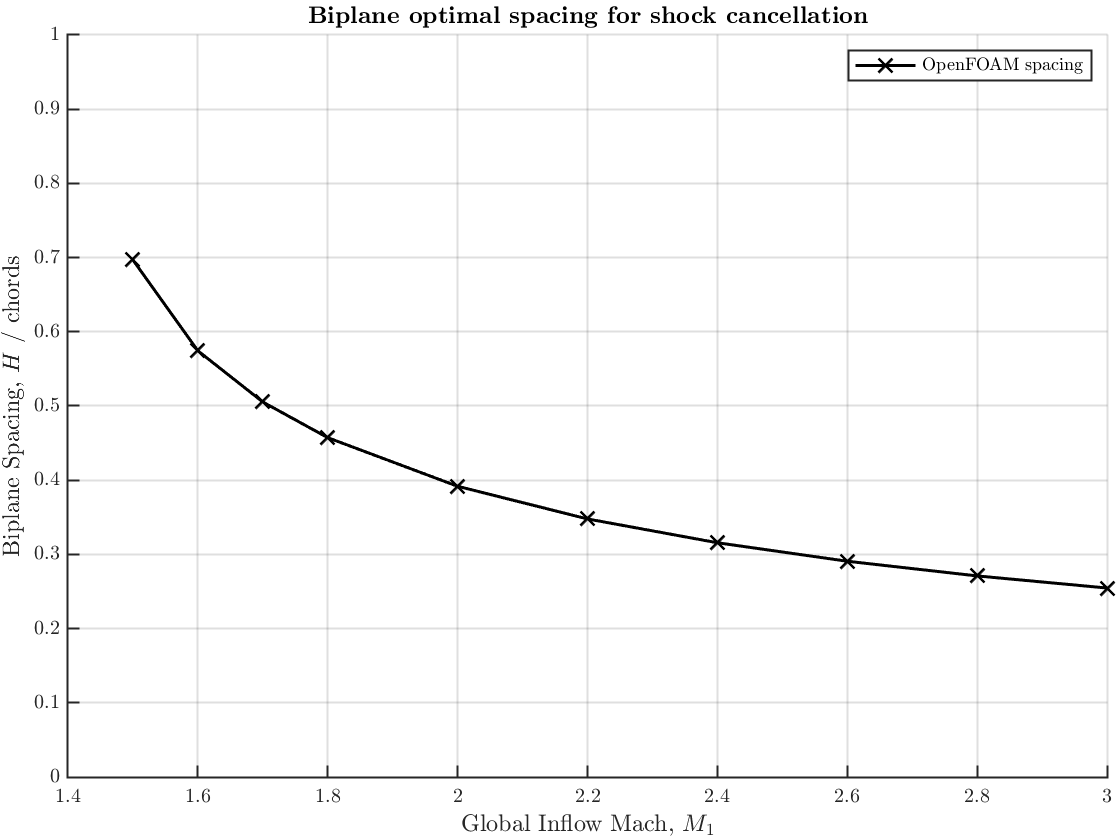


figure
hold on
plot(foam_mach,foam_spacing,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('OpenFOAM spacing','location','northeast','FontSize',legsize)
xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / chords",'FontSize',lsize)
title([{"\textbf{Biplane optimal spacing for shock cancellation}"}],'FontSize',tsize)
ylim([0,1])
    %set ( gca, 'xdir', 'reverse' )
xlim([1.4, 3])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

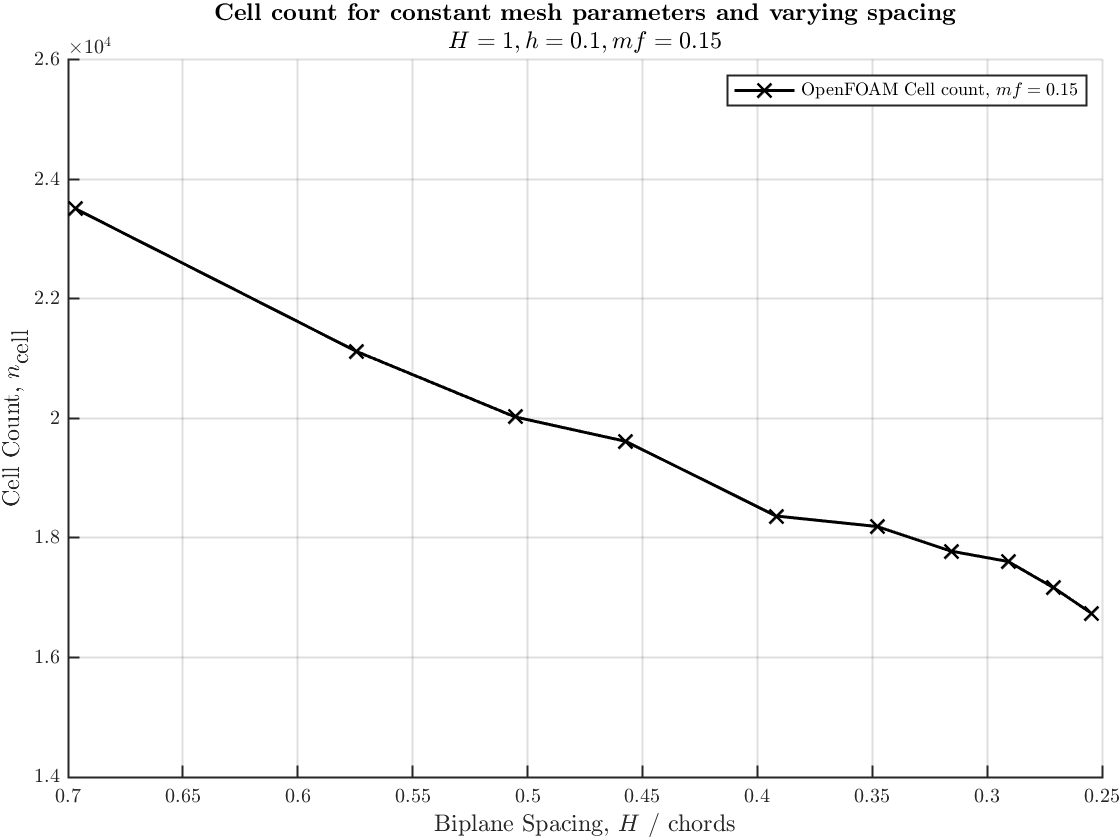


figure
hold on
plot(foam_spacing,foam_cellcount,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('OpenFOAM Cell count, $mf = 0.15$','location','northeast','FontSize',legsize)
xlabel("Biplane Spacing, $H$ / chords",'FontSize',lsize)
ylabel("Cell Count, $n_{\textrm{cell}}$",'FontSize',lsize)
title([{"\textbf{Cell count for constant mesh parameters and varying spacing}","$H=1,h=0.1,mf=0.15$"}],'FontSize',tsize)
ylim([1.4e4,2.6e4])
    set ( gca, 'xdir', 'reverse' )
%xlim([1.4, 3])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

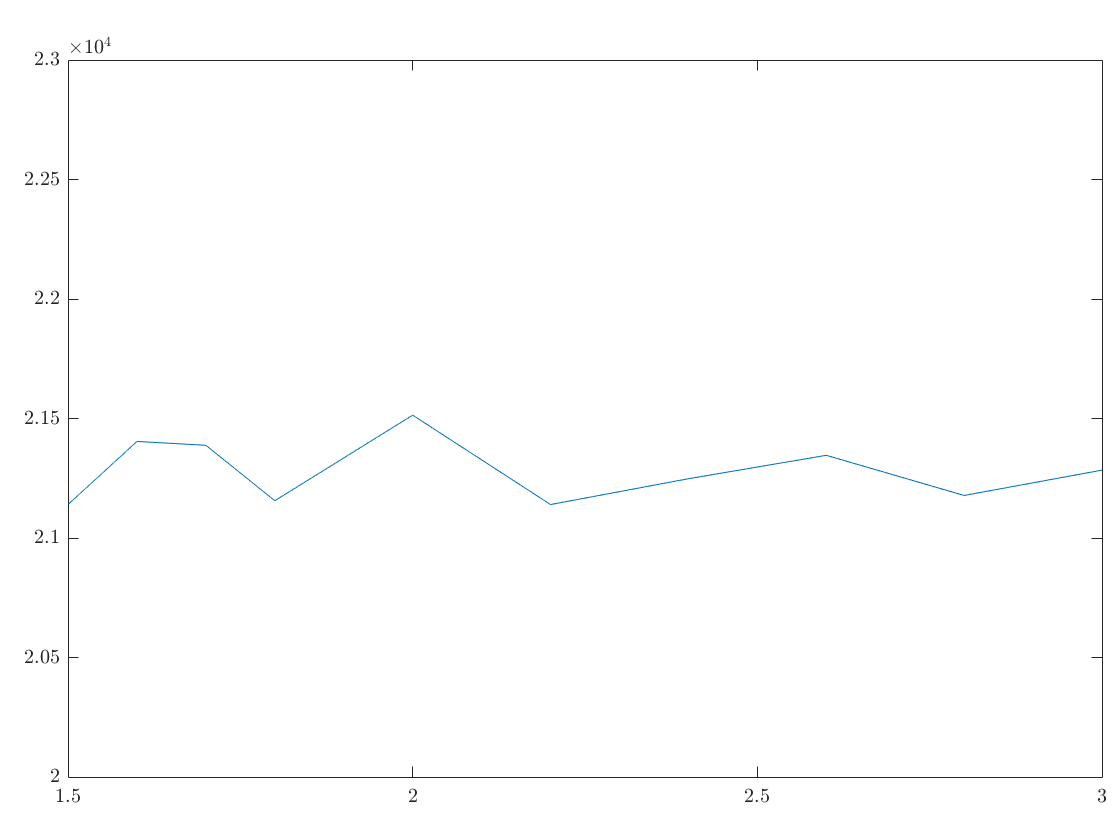


Ma_new = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
H_new = [0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];

ncell_new = [21140,21404,21388,21156,21514,21140,21248,21346,21178,21284];
res_old=[45,51,55,58,64,69,72,76,80,84];

plot(Ma_new,ncell_new)
ylim([20000 23000])
hold off

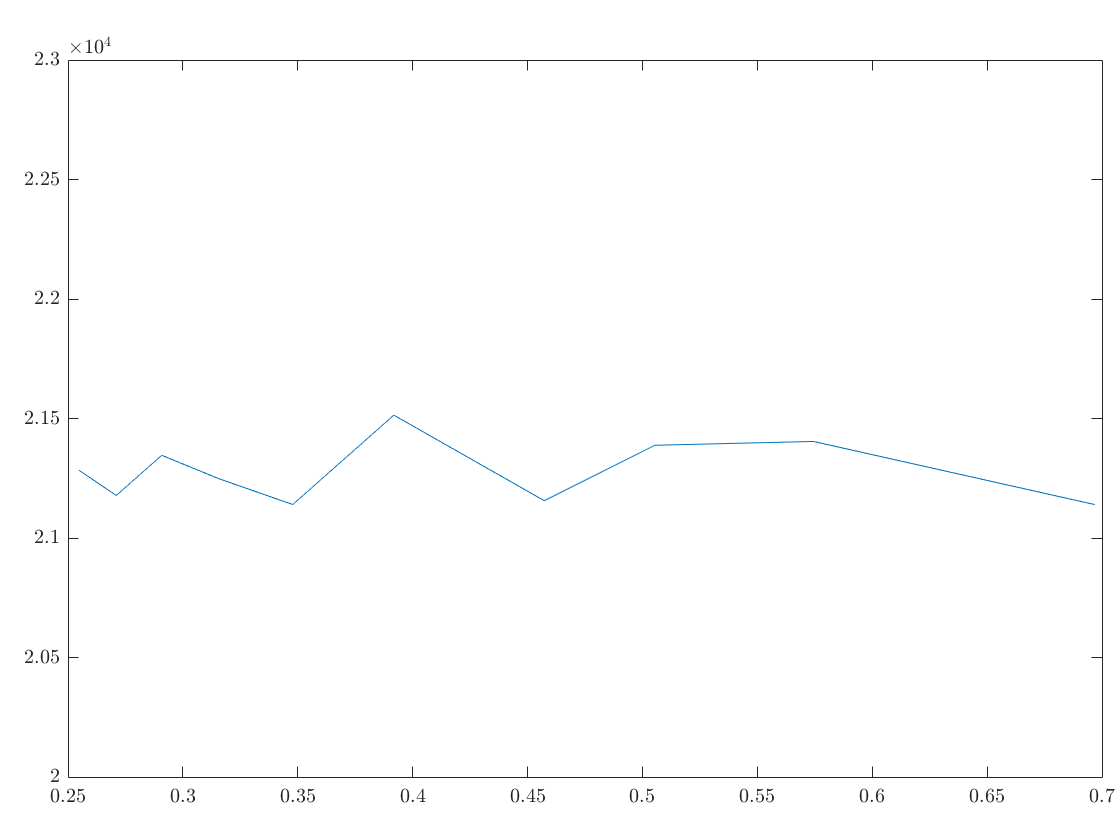

InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

plot(H_new,ncell_new)
ylim([20000 23000])
hold off

InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
H=gca; H.LineWidth=1;

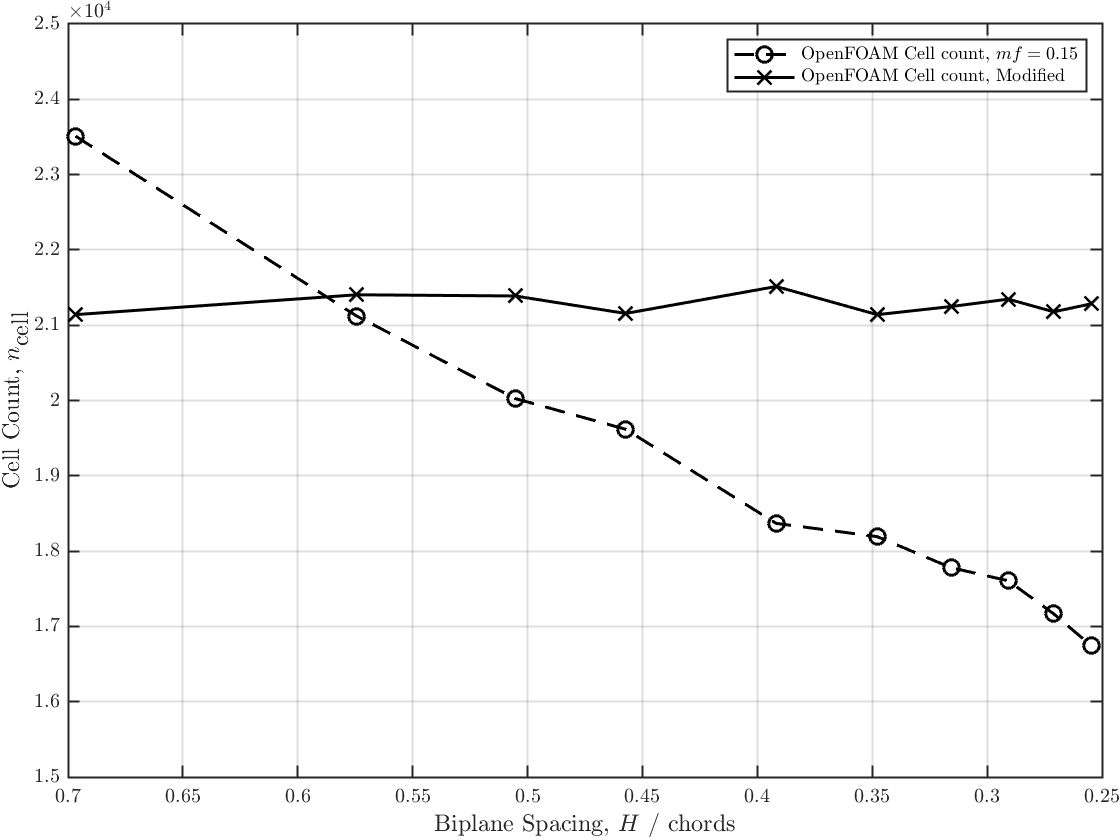


figure
plot(foam_spacing,foam_cellcount,'ko--',"LineWidth",1.5,"MarkerSize",msize)
hold on
plot(H_new,ncell_new,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('OpenFOAM Cell count, $mf = 0.15$','OpenFOAM Cell count, Modified','location','northeast','FontSize',legsize)
xlabel("Biplane Spacing, $H$ / chords",'FontSize',lsize)
ylabel("Cell Count, $n_{\textrm{cell}}$",'FontSize',lsize)
%title([{"\textbf{Cell count for constant mesh parameters and varying spacing}","$H=1,h=0.1,mf=0.15$"}],'FontSize',tsize)
ylim([15000,25000])
xlim([0.25,0.7])
%xlim([1.4, 3])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off
    set ( gca, 'xdir', 'reverse' )
    box on
H=gca; H.LineWidth=1;